% AE6511 Hw6 Problem 7 MATLAB code
% Tomoki Koike 
clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Define the matrices
syms s t alpha T
assume(alpha > 1);
R1 = -alpha;
R2 = 1;
A = 1;
B = 1;
x0 = 0;
xf = 0;

A_tilde = -sqrt(1 - alpha);
W_tilde(t) = int(expm(A_tilde*s)*B*inv(R2)*B.'*expm(A_tilde.'*s),s,0,t)

$$W\_tilde(t) = -\frac{0.5000\,\left({\mathrm{e}}^{-2\,t\,\sqrt{1-\alpha }}-1\right)}{{\left(1-\alpha \right)}^{0.5000}}$$

z0 = expm(A_tilde.'*T)*inv(W_tilde(T))*(expm(A_tilde.'*T)*x0 - xf)

$$z0 = 0$$

syms s(t)
dsolve(diff(s,t) == s^2 + 1)

$$ans = \left(\begin{array}{c} \tan\left(C_{1}+t\right)\\ 1\,\mathrm{i}\\ -1\,\mathrm{i} \end{array}\right)$$

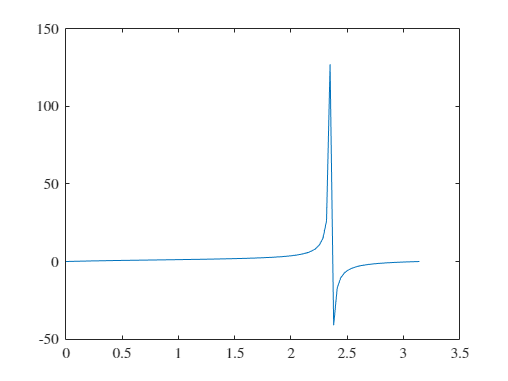

t = linspace(0,pi,100);
plot(t, 1 + tan(t - pi/4))

clear;
R1 = -2;
R2 = 1;
R12 = 0;
A = 1;
B = 1;
x0 = 0;
xf = 0;
A_tilde = A - B*inv(R2)*R12.';
S = B*inv(R2)*B.';
R_tilde = R1 - R12*inv(R2)*R12.';
M = [A_tilde -S; -R_tilde -A_tilde.'];

syms Phi_11(t) Phi_12(t) Phi_21(t) Phi_22(t)
Phi = [Phi_11 Phi_12; Phi_21 Phi_22];
res = dsolve(diff(Phi,t) == M*Phi)

res = struct with fields:
    Phi_21: C3*cos(t) - C1*sin(t)
    Phi_11: C3*(0.5000*cos(t) - 0.5000*sin(t)) - C1*(0.5000*cos(t) + 0.5000*sin(t))
    Phi_12: C4*(0.5000*cos(t) - 0.5000*sin(t)) - C2*(0.5000*cos(t) + 0.5000*sin(t))
    Phi_22: C4*cos(t) - C2*sin(t)


P_tf = res.Phi_22(pi)*inv(res.Phi_12(pi))

Index exceeds the number of array elements. Index must not exceed 1.

Error in sym/subsref (line 997)
            R_tilde = builtin('subsref',L_tilde,Idx);